# Import Data Set

Data = table2struct(readtable('daily (4).csv', 'PreserveVariableNames', true));

## Scrub the Data

[r, c] = size(Data);
fnames = fieldnames(Data);
for i = 1:r 
for j = 3:5
    cfields = Data(i).(fnames{j});
    if isnan(cfields)
        Data(i).(fnames{j}) = 0;
    end
end
for j1 = 8:15
    cfields = Data(i).(fnames{j1});
    if isnan(cfields)
        Data(i).(fnames{j1}) = 0;
    end
end
for j2 = 20:21
    cfields = Data(i).(fnames{j2});
    if isnan(cfields) 
        Data(i).(fnames{j2}) = 0;
    end
end
for j3 = 23:48
    cfields = Data(i).(fnames{j3});
    if isnan(cfields)
        Data(i).(fnames{j3}) = 0;
    end
end
end

## Graphs

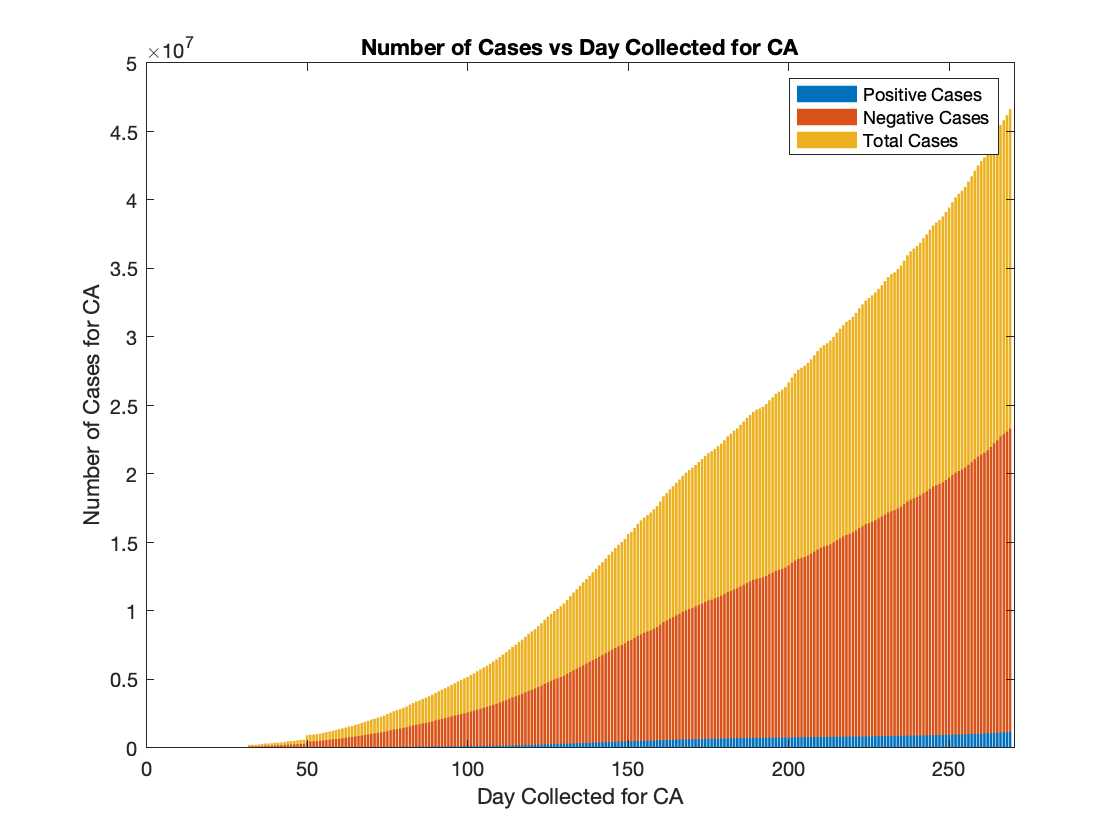

ypos = [zeros(1,269)];
yneg = [zeros(1,269)];
ytot = [zeros(1,269)];
yvent = [zeros(1,269)];
yhosp = [zeros(1,269)];
x = [1:269];
index = 1;
for i2 = r:-1:1
    if Data(i2).(fnames{2}) == 'CA'
        ypos(index) = Data(i2).(fnames{3});
        yneg(index) = Data(i2).(fnames{5});
        ytot(index) = Data(i2).(fnames{8});
        yvent(index) = Data(i2).(fnames{14});
        yhosp(index) = Data(i2).(fnames{10});
        index = index + 1;
    end
end
yfin = [ypos; yneg; ytot];
bar(x,yfin,'stacked')
legend('Positive Cases', 'Negative Cases', 'Total Cases')
ylabel('Number of Cases for CA');
xlabel('Day Collected for CA');
title('Number of Cases vs Day Collected for CA')

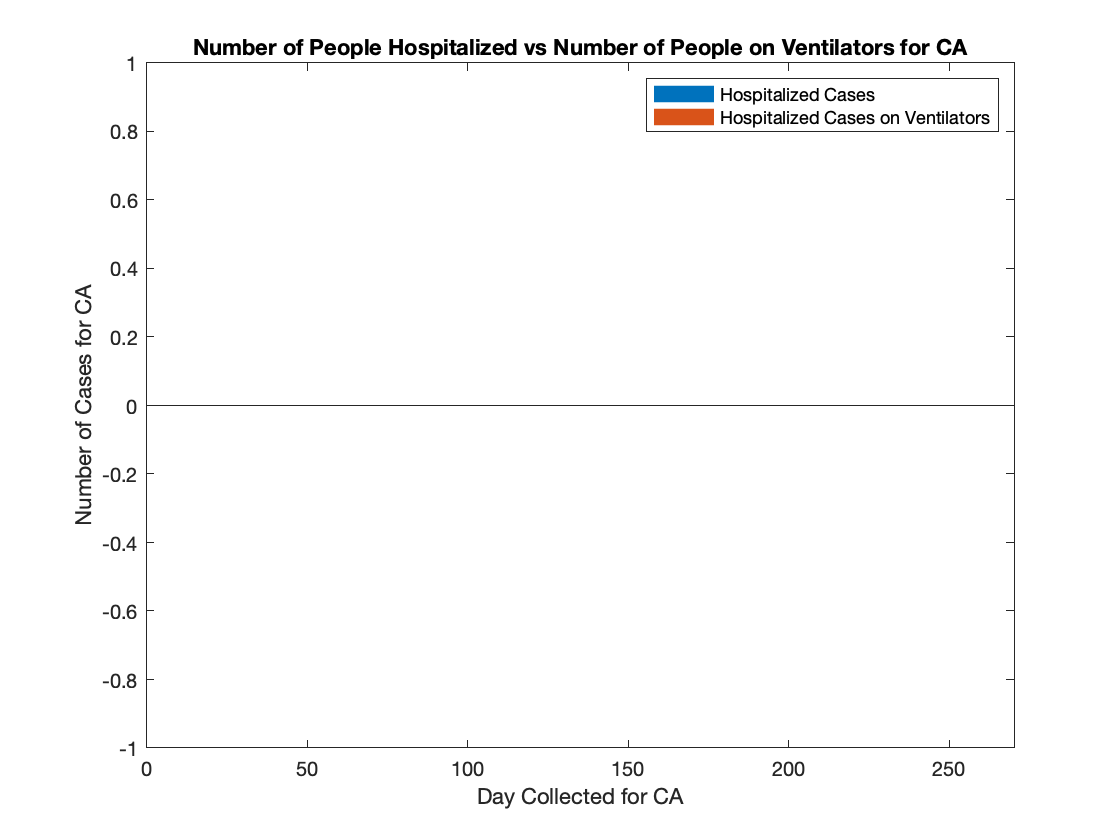

yfin1 = [yvent; yhosp];
bar(x,yfin1,'stacked')
legend('Hospitalized Cases', 'Hospitalized Cases on Ventilators')
ylabel('Number of Cases for CA');
xlabel('Day Collected for CA');
title('Number of People Hospitalized vs Number of People on Ventilators for CA')